% K_0 * K_d = 1
zeta = 1; % damping ratio
B_L = 10; % noise bandwidth in Hz

periods_per_second = 1000;
integrate_periods = 1;
T = integrate_periods / periods_per_second; % loop filter sampling time in s
omega_n = 8 * zeta * B_L / ((4 * zeta^2) + 1); % loop filter natural frequency 

C_1 = 8 * zeta * omega_n * T / (4 + (4 * zeta * omega_n * T) + (omega_n * T)^2);
C_2 = 4 * (omega_n * T)^2 / (4 + 4 * zeta * omega_n * T + (omega_n * T)^2);

a = [0, 0];
b = [0, 0];

% y[k] = (C_1 + C_2) * x[k] + y[k - 1] - C_1 * x[k - 1]
b (1) = C_1 + C_2; % x[k]
a (1) = 1;         % y[k]
a (2) = -1;        % y[k-1]
b (2) = -C_1;      % x[k-1]

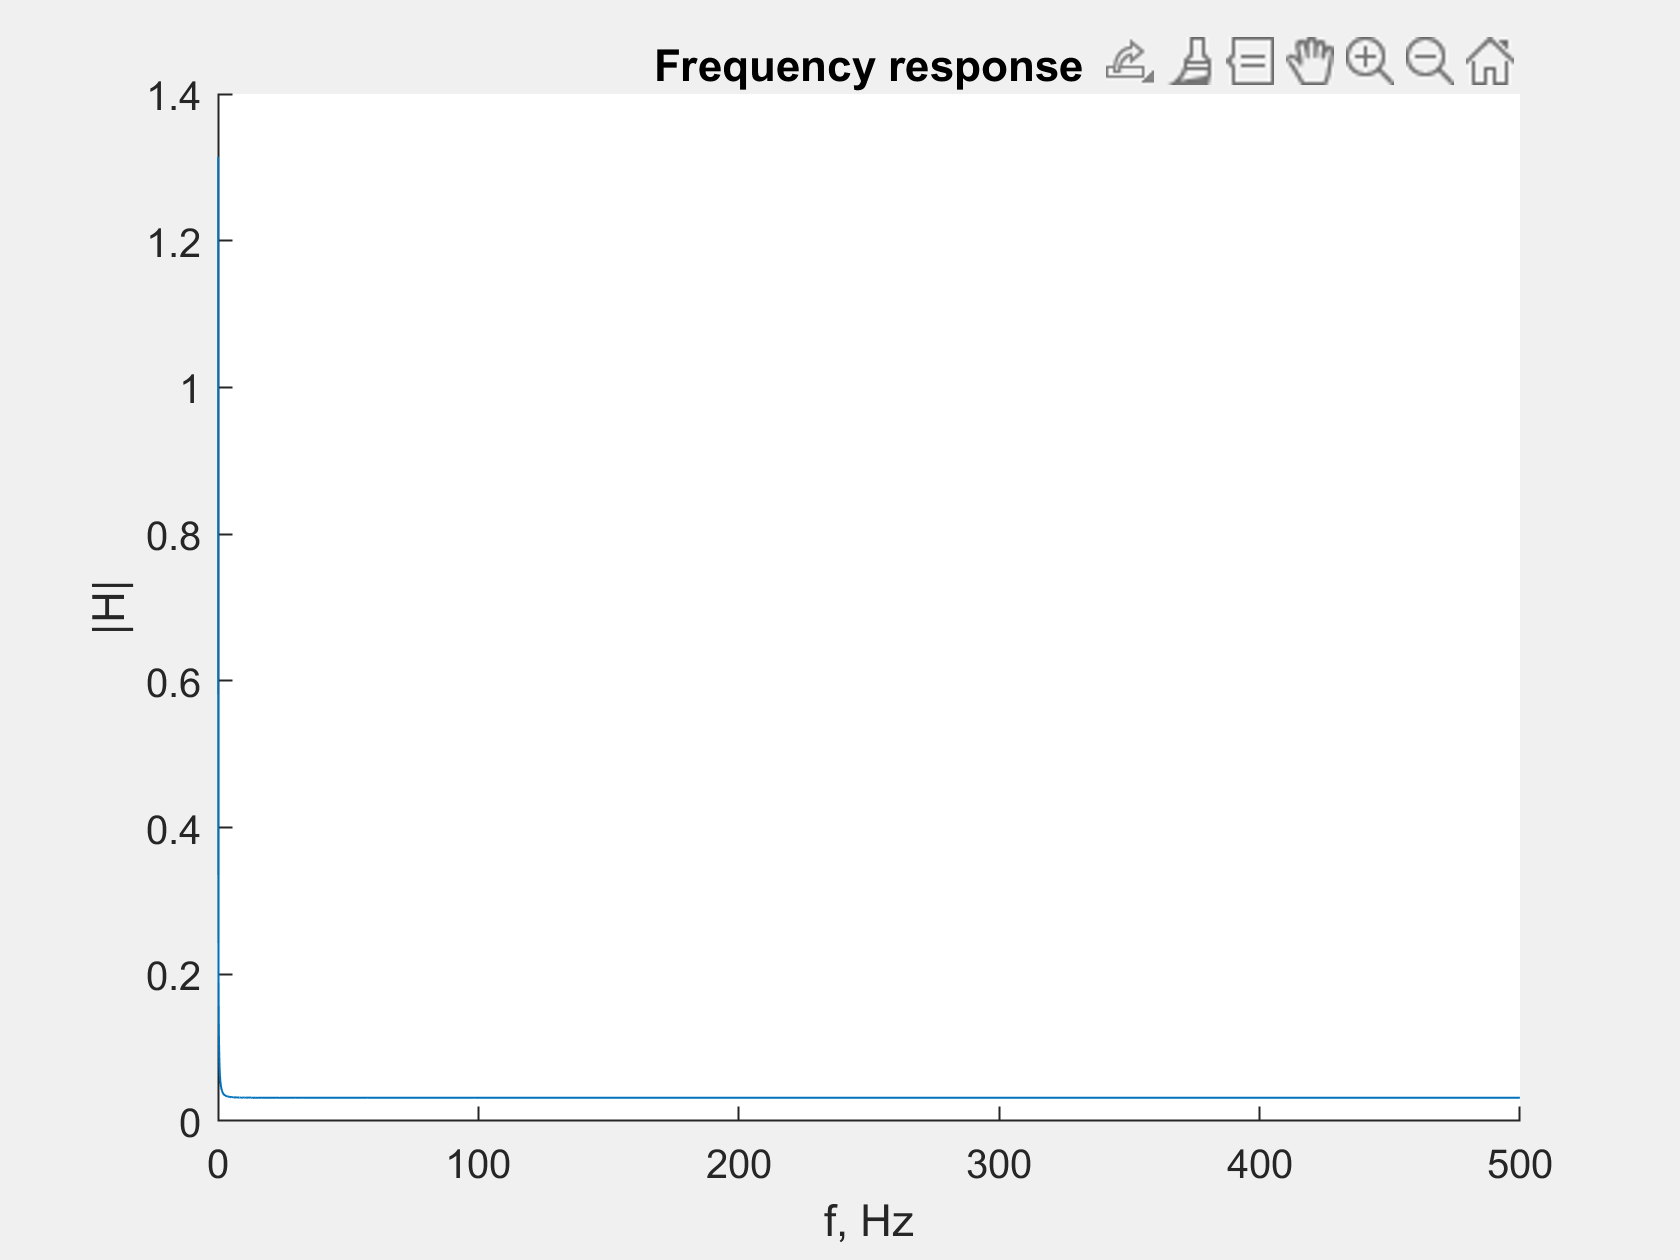

points_number = 16384;
f_s = 1 / T;
[H, w] = freqz (b, a, points_number, f_s);

% frequency response plot
fig_FR = figure;
set (fig_FR, 'Visible', 'on');
hold on;
plot (w, abs (H));
xlabel ('f, Hz');
ylabel ('|H|');
title ('Frequency response');
hold off;
savefig (fig_FR, 'FR.fig');
saveas (fig_FR, 'FR.jpeg');